# Industrial Machinery Anomaly Detection

# Part 1: Data Preparation and Feature Extraction

## Load Data

load("IndustrialMachineData.mat")

## Visualize Normal and Abnormal data

Visualize normal vs abnormal data across channels for one member of the ensemble

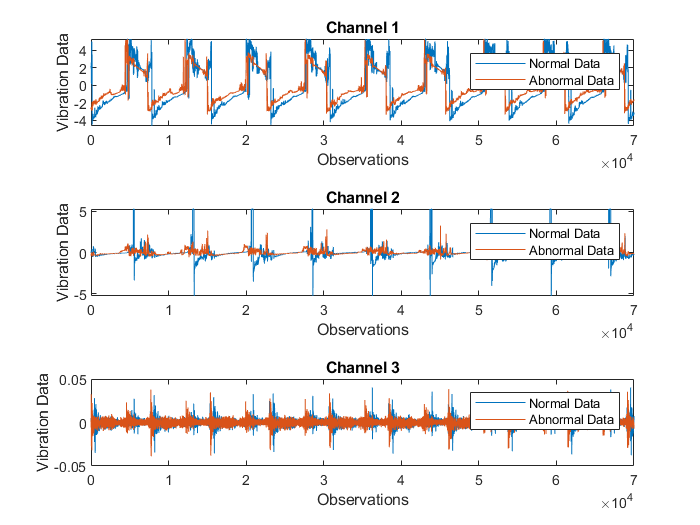

tF = trainData.label == 1;
normalData = trainData(tF,:);
abnormalData = trainData(~tF,:);

ensMember = 5;

plotVibrationData(normalData, abnormalData, ensMember)

## Extract Features with Diagnostic Feature Designer App

Now that we have our data loaded in memory, it is often challenging to determine which features to select and how important these features are. The [Diagnostic Feature Designer App](matlab: web(fullfile(docroot, 'predmaint/ref/diagnosticfeaturedesigner-app.html'))) from the Predictive Maintenance Toolbox simplifies this workflow by interactively allowing you to explore your data visually by plotting and interacting with your ensemble memebers together, convert your data into different forms (time-domain vs frequency-domain), generate features of various types, and rank these features to establish which ones are the most effective. You can then generate a script that can re-process these features.

The following command will bring up the app, or you can find it in the Apps tab.

The features below were chosen using a progonostic ranking technique. 

- Ch1 : Crest Factor, Kurtosis, RMS, Std

- Ch2 : Mean, RMS, Skewness, Std

- Ch3 : Crest Factor, SINAD, SNR, THD

This visualization from the Diagnostic Feature Designer App shows the distributions separated by labels for various features extracted from Ch1.

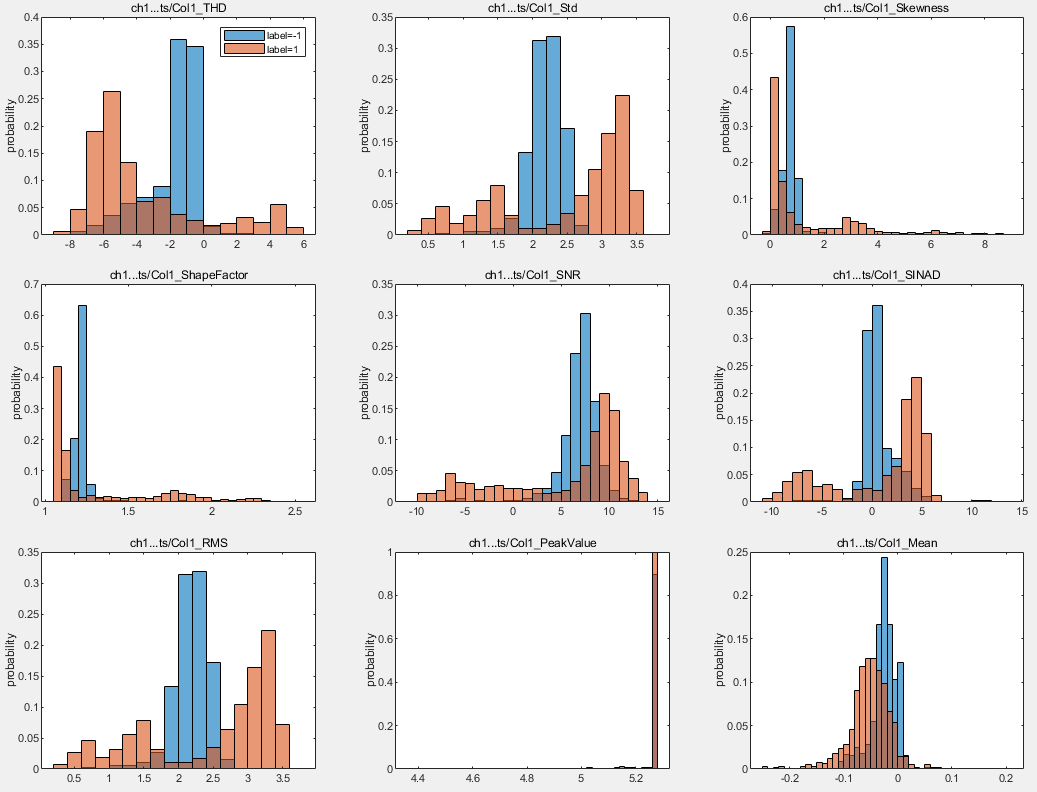

Once we have our features extracted, we can generate a MATLAB function from the app that will repeat the process that we just completed interactively.

trainFeatures = generateFeatures(trainData);

Copyright 2021 The MathWorks, Inc.